# Exercici 7 de Laboratori

## Sistema semi-automàtic per segmentar objectes

(Per Francesc Forn, Raúl Lumbreras i Martí Vall)

### K-means de HSV

L’objectiu de la sessió és implementar un sistema semi-automàtic per segmentar objectes o animals en imatges en color. Utilitzarem una segmentació simple per color utilitzant kmeans. Les imatges a tractar presentaran un objecte molt diferenciat del seu fons pels seus colors.

El procediment del programa realitzat seria el següent: l’usuari indica manualment l’objecte a segmentar amb un marc rectangular i la resposta de l’aplicació serà l’objecte segmentat indicat amb el seu perfil en vermell. 

Comencem obrint una imatge i comprovant que és una imatge RGB, fent servir la instrucció *size. *Mostrem la imatge per pantalla amb *imshow.* 

I = imread("flor.png");
size(I,3)

ans = 3

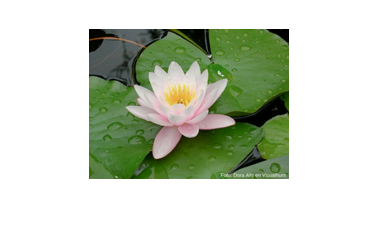

imshow(I);

Obtenim de l'usuari el rectangle que emmarca l’objecte que vol segmentar*:*

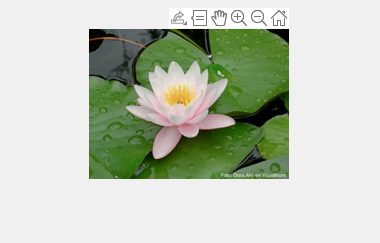

rect = getrect;

Obtenim la imatge **HSV (t**ambé es pot fer en altres espais de color com CIE Lab).

IHSV = rgb2hsv(I);

Preparem la taula pel *kmeans*. Cal construir una taula **O** amb tantes files com píxels i les següents columnes: [Hx Hy S V] On Hx Hy són les coordenades circulars 2D del hue.

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1)];
      %Treure component x Treure component y del hue

Agrupem els colors en **k** classes amb kmeans i obtenim la classificació **C**, per exemple  k = 20;  **C**= kmeans(**O**,k);  

k = 20;
C = kmeans(O,k);

Per veure el resultat obtingut executem el següent codi: IC = reshape(C,f,c); rgb = label2rgb(IC); imshow(rgb).

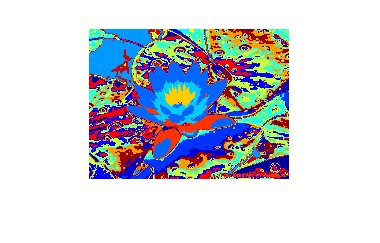

IC = reshape(C,[size(I,1)],[size(I,2)]);

rgb = label2rgb(IC);
imshow(rgb);

Ara la idea és veure quins colors cauen a dins del rectangle i quins fora. Per tal fi, construïm una imatge de valors booleans anomenada **MASK** de la mateixa mida que **I** amb els valors a zero si està fora del rectangle i 1 si està dins.

MASK = zeros(size(I,1),size(I,2));
MASK(rect(2):(rect(2)+rect(4)),rect(1):(rect(1)+rect(3))) = 1;

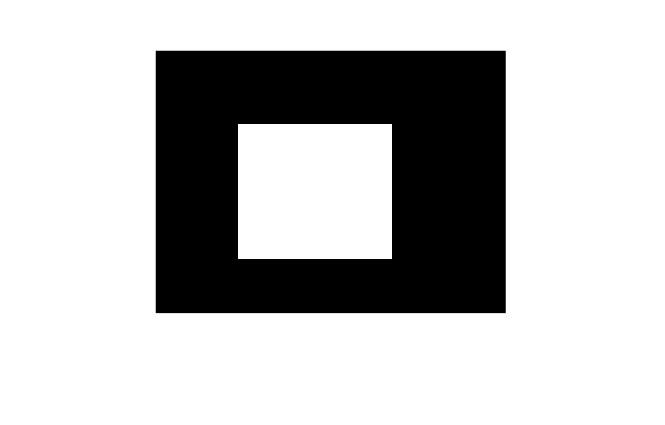

imshow(MASK);

Ara construïm un vector **H** que indicarà si un color cau dins del rectangle o no. Tal que H = [C, MASK(:)]; Observem que H és una taula que indica si tal color C és dins o fora de la mascara.

H = [C, MASK(:)];

A continuació, comptem per a cada color de C quants píxels han caigut a fora i quants a dins. Guardem els resultats en dos arrays **Hist0** i **Hist1**. Evidentment, la mida de Hist0 i Hist1 ha de ser igual al nombre de classes *k*.

Hist0 = hist(H(H(:,2)==0),[1:k]); % H(:,2) == 0 retorna els valors fora del rectangle, 
                                  % H(H(:,2)==0) retorna els valors C de fora del rectangle
Hist1 = hist(H(H(:,2)==1),[1:k]); % El mateix pels punts de dins

Llavors decidim si un representant de color pertany a la figura que es vol segmentar comparant les seves aparicions dins i fora del rectangle. Guardem la decisió en un vector anomenat ***RES***. Quelcom com RES = Hist1 > Hist0;

RES = Hist1 > Hist0;

Per anar acabant decidim per a cada  píxel de la matriu **H** si forma part de la figura o no utilitzant la informació que conté el vector **RES**. Guardem el resultat en un vector **M** i el mostrem per pantalla (fig 6).

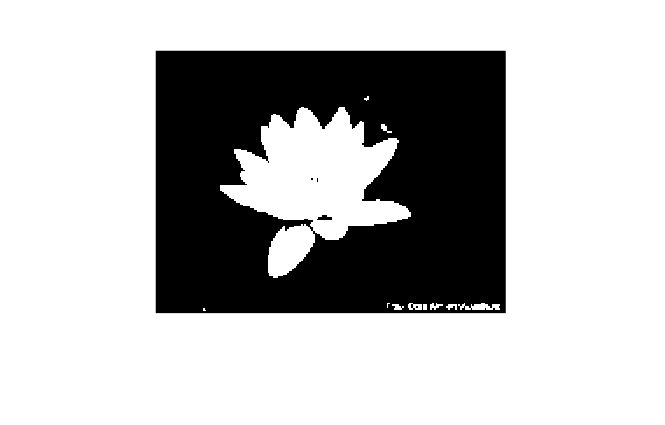

M = RES(H(:,1)); %Elements d'H que cauen tenen una k a 1 a RES
MFin = reshape(M,size(I,1),size(I,2));
imshow(MFin);

I per últim filtrem la imatge per a que el resultat no sigui tant sorollós i més compacte.

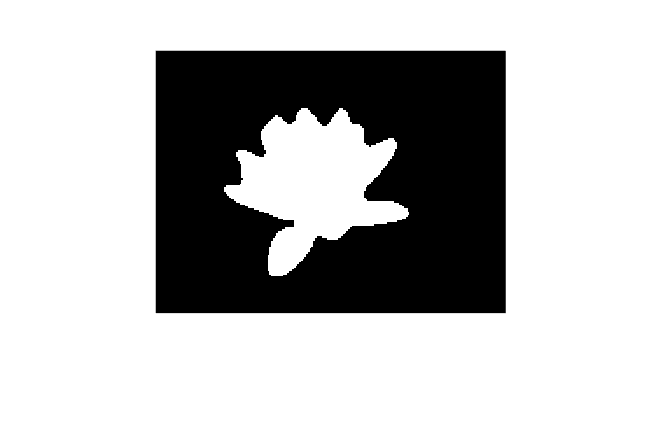

se = strel('disk',4);
MFinClean = medfilt2(MFin,[7 7]);
%MFinClean = imopen(MFin,se);

imshow(MFinClean)

### Altres K-means

En aquest apartat considerem altres fons d’informació per fer el k-means, tals com la posició o altres espais de color. 

#### HSV amb Posició

Provarem afegir al procediment anterior les components de la posició de cada píxel normalitzada al càlcul dels k-means:

I = imread("flor.png");
imshow(I);
rect = getrect();

IHSV = rgb2hsv(I);

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1) reshape(xc,[],1) reshape(yc,[],1)];

k = 25;
[rgb,MFin] = my_kmeans(I,O,k,rect);

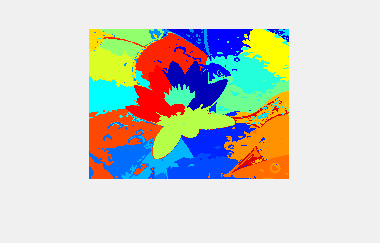

imshow(rgb);

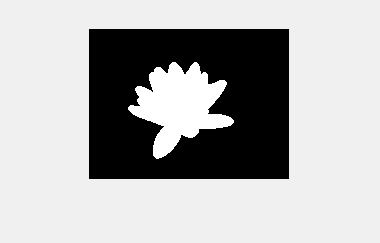

se = strel('disk',4);
MFinClean = imopen(MFin,se);
imshow(MFinClean)

Veiem que en aquest cas la imatge es segmenta adequadament.

Repetim aquest procediment per a una altra imatge senzilla, amb elevat contratst entre l'objecte i el fons:

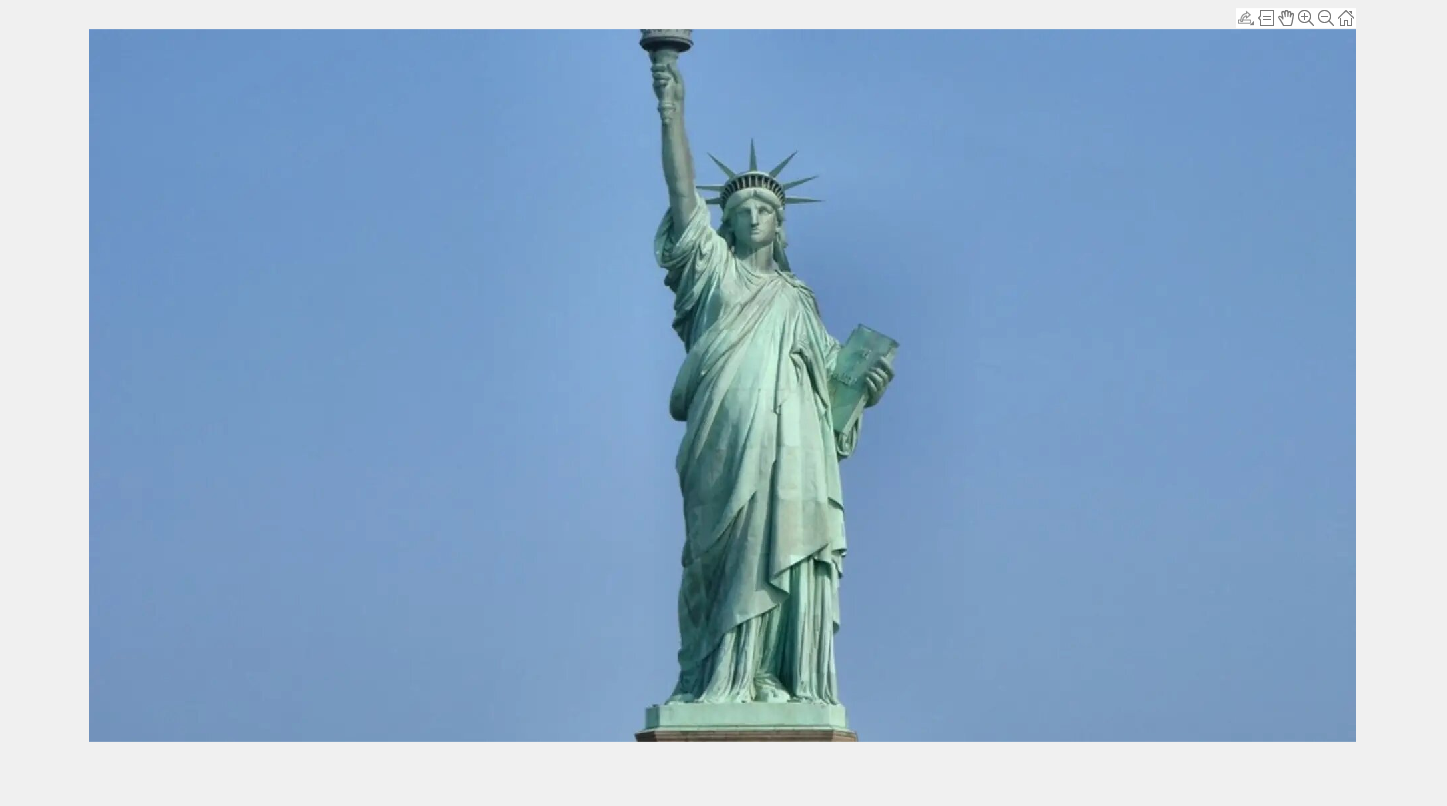

I = imread("ls.jpg");
imshow(I);
rect = getrect();

IHSV = rgb2hsv(I);

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1) reshape(xc,[],1) reshape(yc,[],1)];

k = 20;
[rgb,MFin] = my_kmeans(I,O,k,rect);

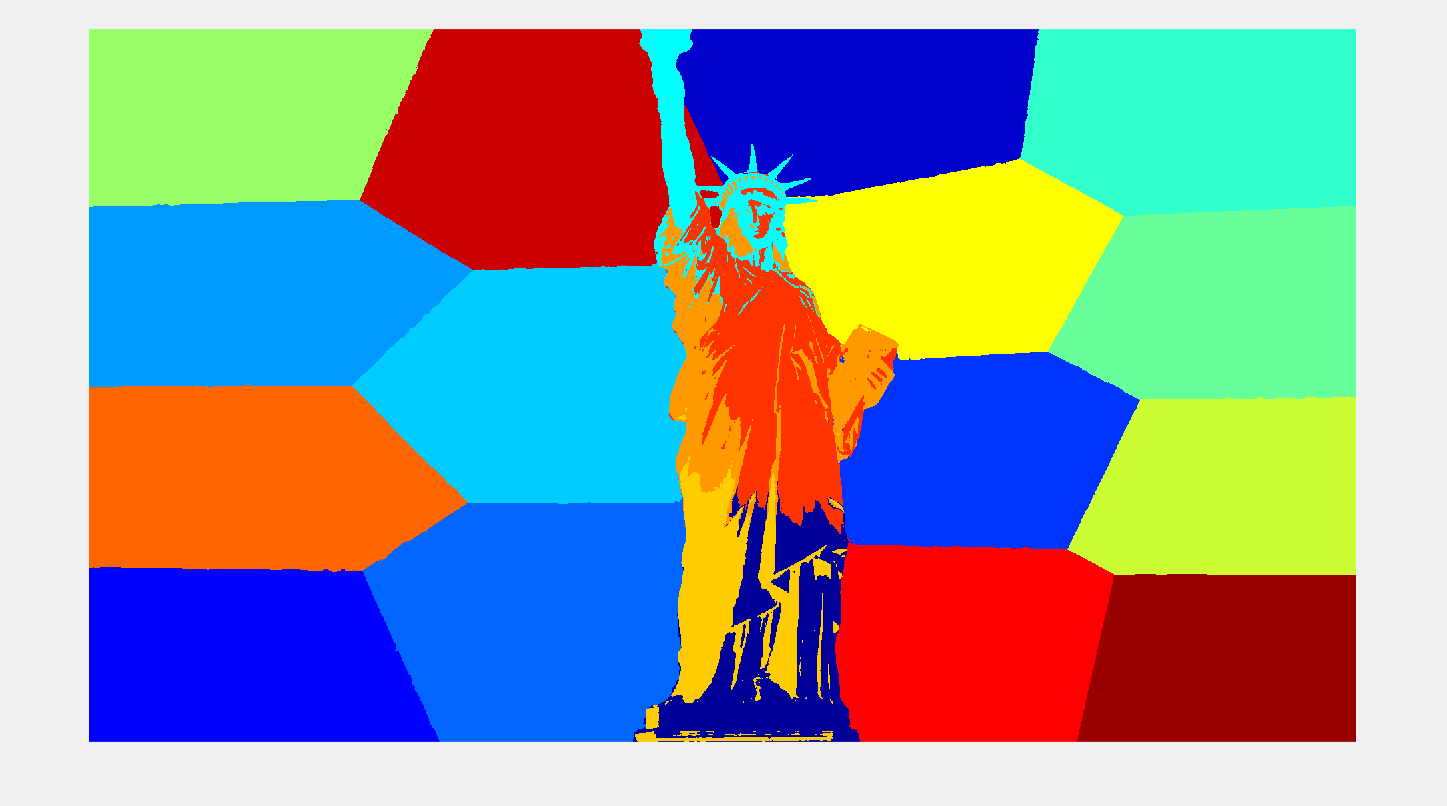

imshow(rgb);

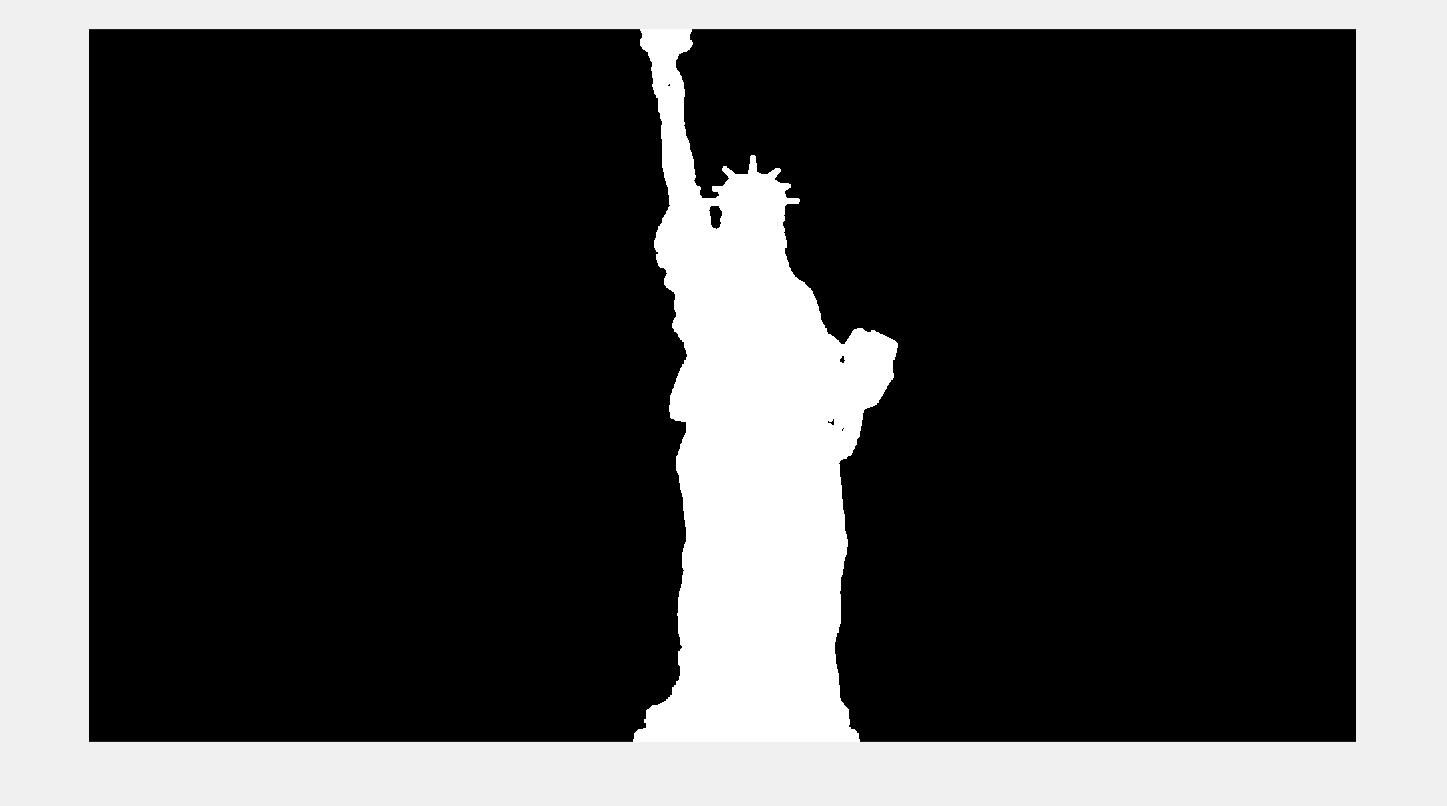

se = strel('disk',5);
MFinClean = imopen(MFin,se);
imshow(MFinClean)

Veiem que en aquest cas es fa una molt bona segmentació tant en la imatge rgb com en el resultat.

Repetim aquest procediment per a una imatge més complexa:

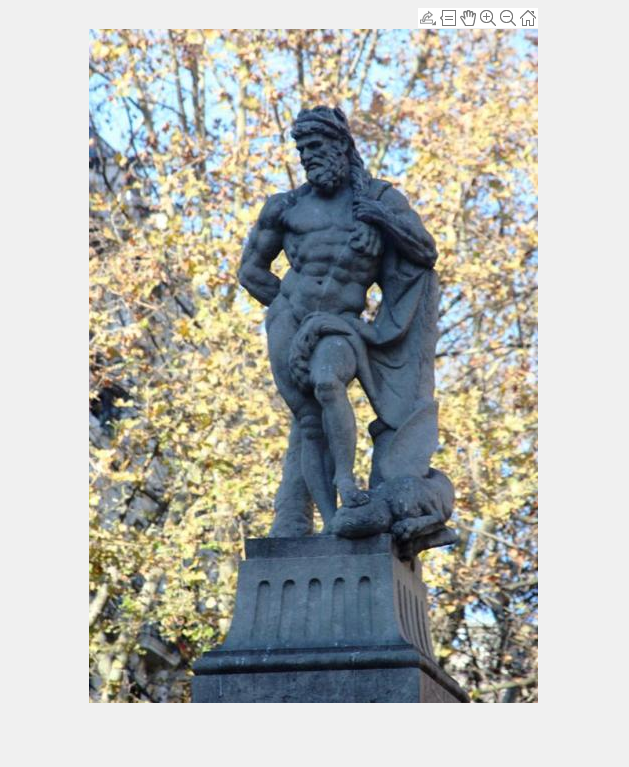

I = imread("mscl.jpeg");
imshow(I);
rect = getrect();

IHSV = rgb2hsv(I);

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1) reshape(xc,[],1) reshape(yc,[],1)];

k = 20;
[rgb,MFin] = my_kmeans(I,O,k,rect);

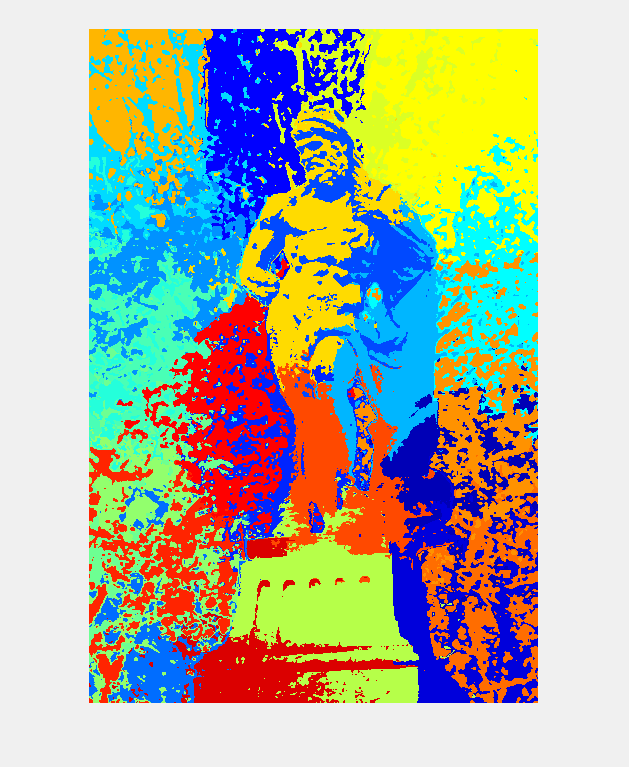

imshow(rgb);

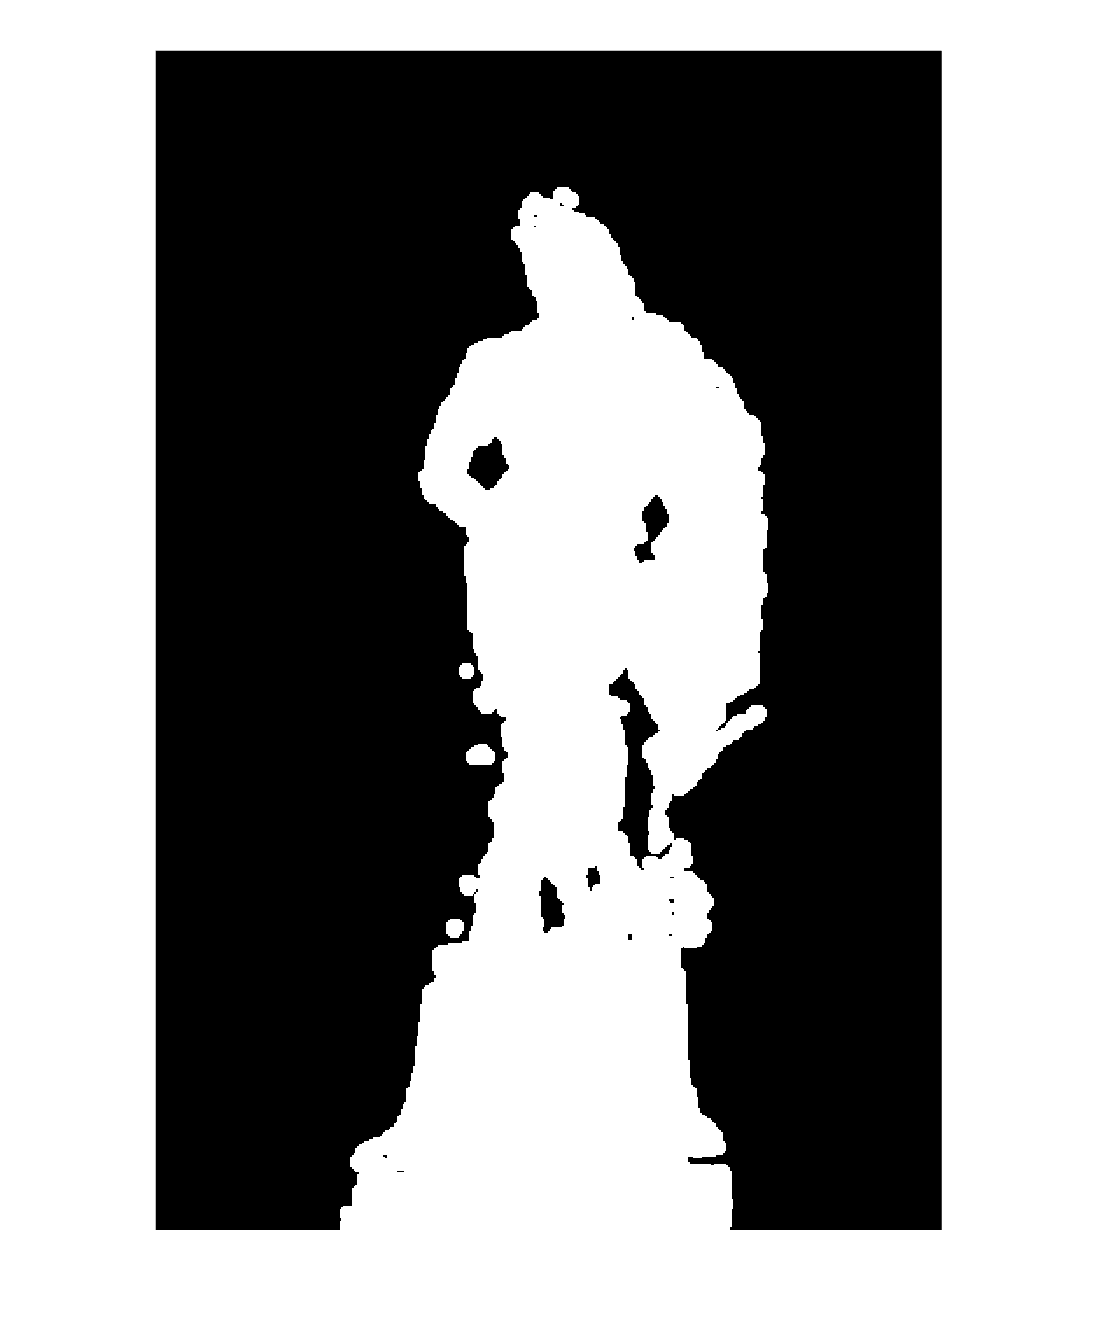

se = strel('disk',5);
MFinClean = imopen(MFin,se);
imshow(MFinClean)

En aquest cas, al tractar-se d'una imatge més complexa amb més detall al fons, el resultat no és tant net, i hi ha falsos positius.

Resulta clar, doncs, que com més llisa sigui la imatge, i més contrast tingui l'objecte amb el fons, millors resultats obtindrem.

#### CIE Lab

Probarem de fer el procés, ara emprant un espai de color diferent, el CIE Lab.

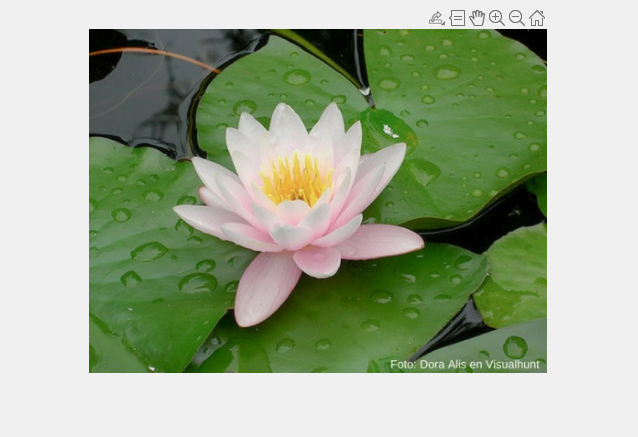

I = imread("flor.png");
imshow(I);
rect = getrect();

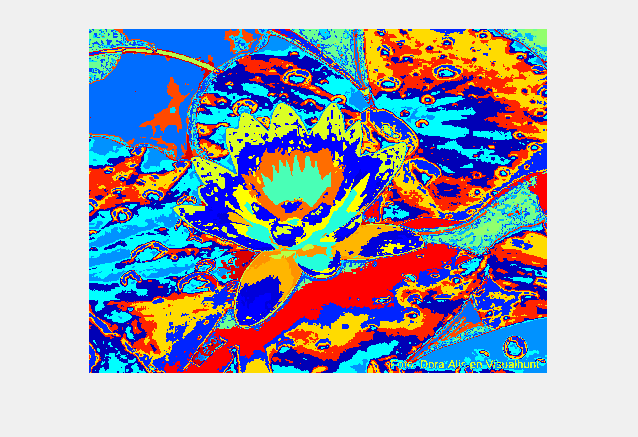

ILAB = rgb2lab(I);

L = IHSV(:,:,1);
A = IHSV(:,:,2);
B = IHSV(:,:,3);

O =  [reshape(L,[],1) reshape(A,[],1) reshape(B,[],1)];

k = 25;
[rgb,MFin] = my_kmeans(I,O,k,rect);
imshow(rgb);

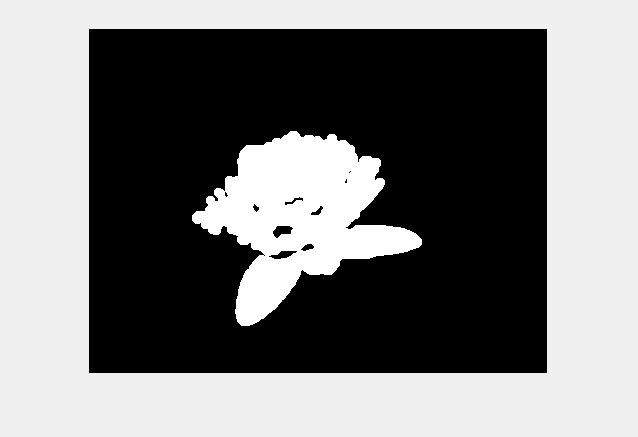

se = strel('disk',5);
MFinClean = imopen(MFin,se);
imshow(MFinClean)

Veiem que s'obté pitjor que amb HSV, però tot i això resulta possible identificar l'objecte.

#### CEL Lab amb Posició

Per últim, tal i com hem fet amb HSV; afegim a CEL Lab les posicions en l'espai:

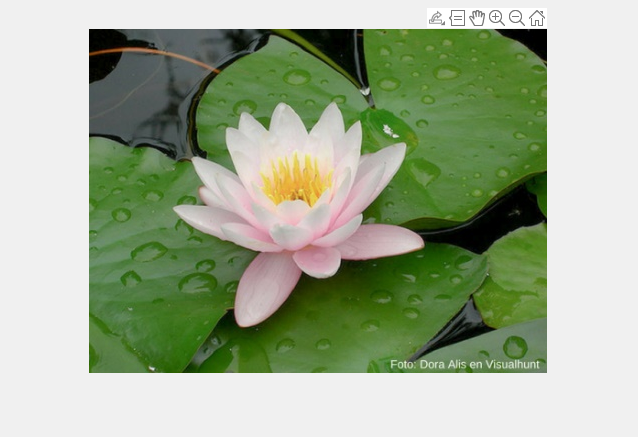

I = imread("flor.png");
imshow(I);
rect = getrect();

ILAB = rgb2lab(I);
ILAB = rgb2lab(I);

L = IHSV(:,:,1);
A = IHSV(:,:,2);
B = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(L,[],1) reshape(A,[],1) reshape(B,[],1) reshape(xc,[],1), reshape(yc,[],1)];

k = 20;
[rgb,MFin] = my_kmeans(I,O,k,rect);

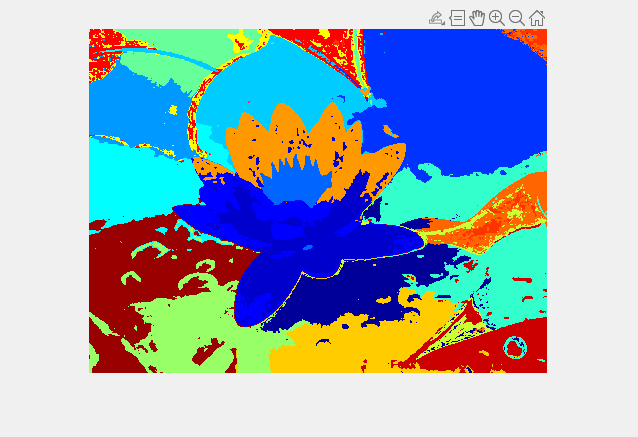

imshow(rgb);

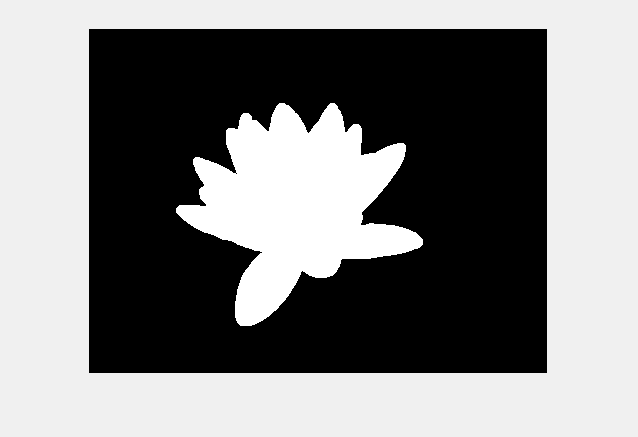

se = strel('disk',5);
MFinClean = imopen(MFin,se);
imshow(MFinClean)

Veiem que afegir les posicions millora el resultat anterior.

### K-means sense finestra dinàmica

En aquest apartat experimentem si es possible segmentar sense la finestra, suposant p.ex. que l’objecte està centrat en la imatge.En aquest apartat no intentarem deduïr informació de les dades, com p. ex. d'histogrames, sino que ens centrarem en definir diferents finestres estàtiques i veure com afecten aquestes als resultats.

Així doncs comencem el procediment com sempre:

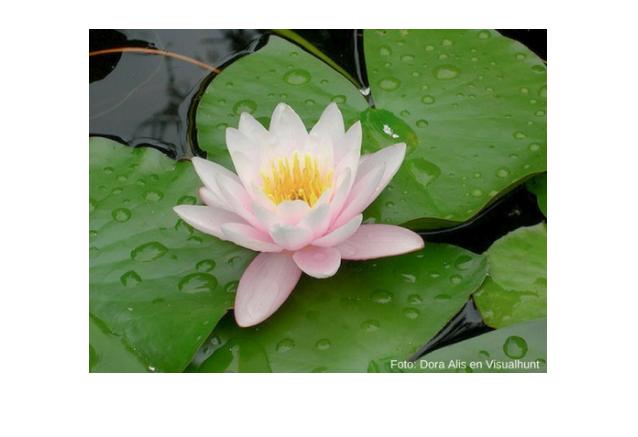

I = imread("flor.png");
imshow(I);

Definim tres tamanys de finestra per fer el k-means i veiem com afecta això als resultats:

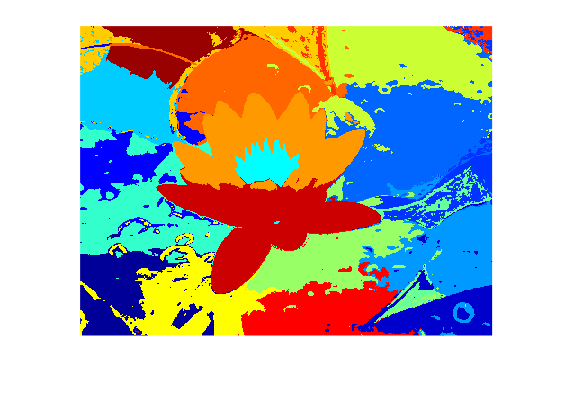

x = size(I,1);
y = size(I,2);

finestraPetita = [round(2*x/5), round(3*x/5), round(2*y/5), round(3*y/5)];
MASKP = zeros(x,y);
MASKP(finestraPetita(1):finestraPetita(2),finestraPetita(3):finestraPetita(4)) = 1;

finestraMitjana = [round(1*x/3), round(2*x/3), round(y/3), round(2*y/3)];
MASKM = zeros(x,y);
MASKM(finestraMitjana(1):finestraMitjana(2),finestraMitjana(3):finestraMitjana(4)) = 1;

finestraGran = [round(1*x/4), round(3*x/4), round(1*y/4), round(3*y/4)];
MASKG = zeros(x,y);
MASKG(finestraGran(1):finestraGran(2),finestraGran(3):finestraGran(4)) = 1;

IHSV = rgb2hsv(I);

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1) reshape(xc,[],1) reshape(yc,[],1)];

k = 20;

[rgb,MFinP] = my_kmeans_c(I,O,k,MASKP);
[rgb,MFinM] = my_kmeans_c(I,O,k,MASKM);
[rgb,MFinG] = my_kmeans_c(I,O,k,MASKG);

imshow(rgb);

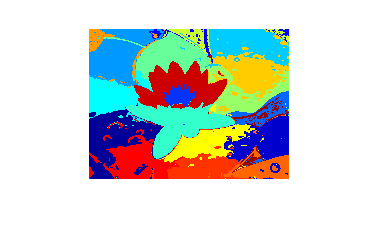

imshow(rgb);

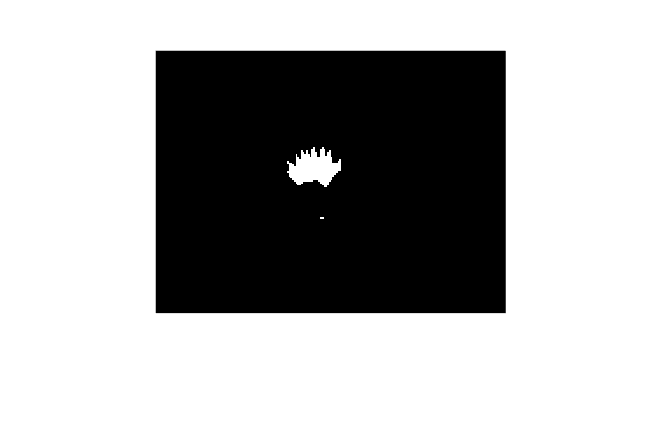

imshow(MFinP)

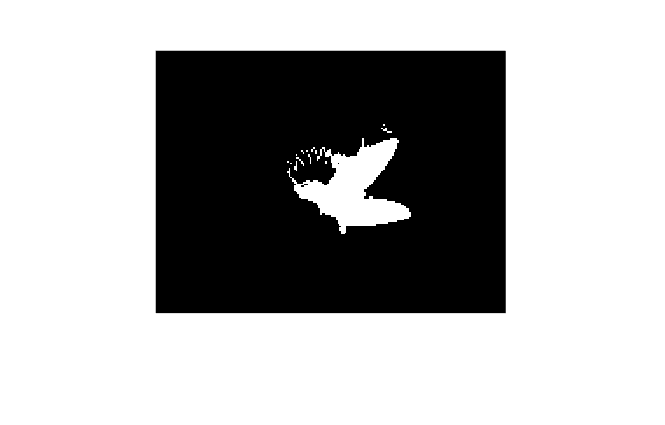

imshow(MFinM)

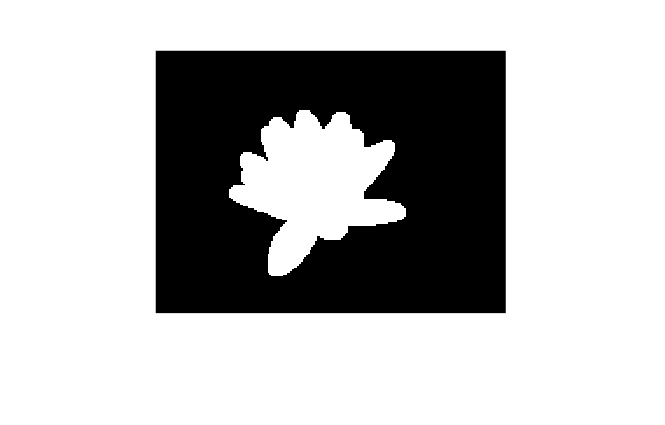

se = strel('disk',5);
MFinClean = imopen(MFinG,se);
imshow(MFinClean)

En el cas d'aquesta imatge, la finestra petita detecta tan sols els estambres i pístil, la mitjana comença a detectar petals, i la gran ja detecta tota la flor.

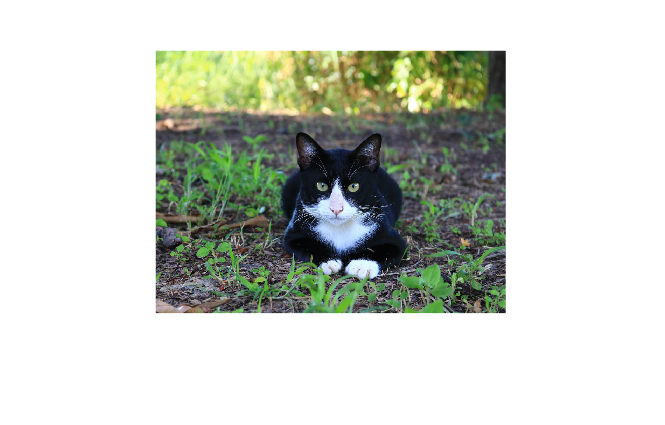

I = imread("gat.jpg");
imshow(I);

x = size(I,1);
y = size(I,2);

finestraPetita = [round(2*x/5), round(3*x/5), round(2*y/5), round(3*y/5)];
MASKP = zeros(x,y);
MASKP(finestraPetita(1):finestraPetita(2),finestraPetita(3):finestraPetita(4)) = 1;

finestraMitjana = [round(1*x/3), round(2*x/3), round(y/3), round(2*y/3)];
MASKM = zeros(x,y);
MASKM(finestraMitjana(1):finestraMitjana(2),finestraMitjana(3):finestraMitjana(4)) = 1;

finestraGran = [round(1*x/4), round(3*x/4), round(1*y/4), round(3*y/4)];
MASKG = zeros(x,y);
MASKG(finestraGran(1):finestraGran(2),finestraGran(3):finestraGran(4)) = 1;


IHSV = rgb2hsv(I);

Hx = cos(IHSV(:,:,1))/size(I,1);
Hy = sin(IHSV(:,:,1))/size(I,2);
S = IHSV(:,:,2);
V = IHSV(:,:,3);

w = size(I,2);
h = size(I,1);

xc = (1:w);
xc = ones(h,1)*xc/w;
yc = (1:h);
yc = yc'*ones(1,w)/h;

O =  [reshape(Hx,[],1) reshape(Hy,[],1) reshape(S,[],1) reshape(V,[],1) reshape(xc,[],1) reshape(yc,[],1)];

k = 15;

[rgb,MFinP] = my_kmeans_c(I,O,k,MASKP);

[rgb,MFinM] = my_kmeans_c(I,O,k,MASKM);

[rgb,MFinG] = my_kmeans_c(I,O,k,MASKG);

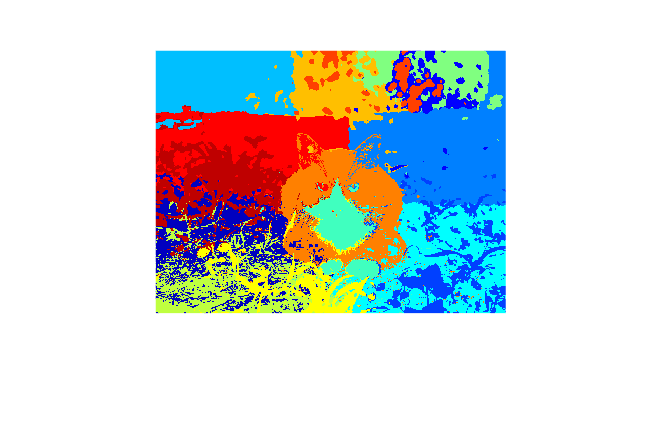

imshow(rgb);

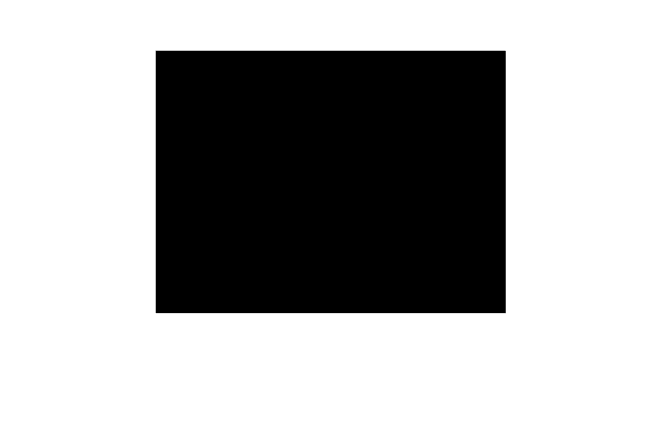

imshow(MFinP);

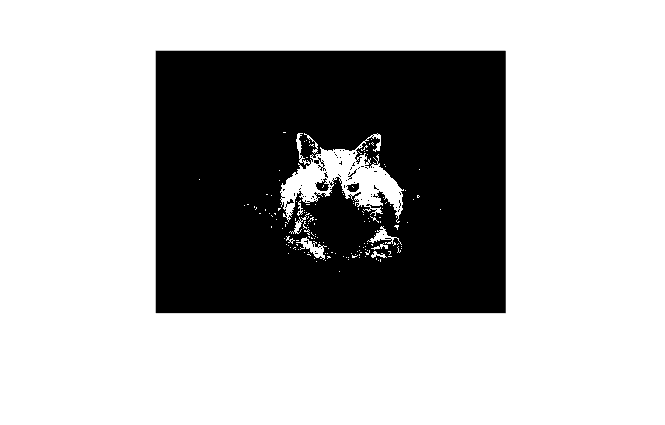

imshow(MFinM);

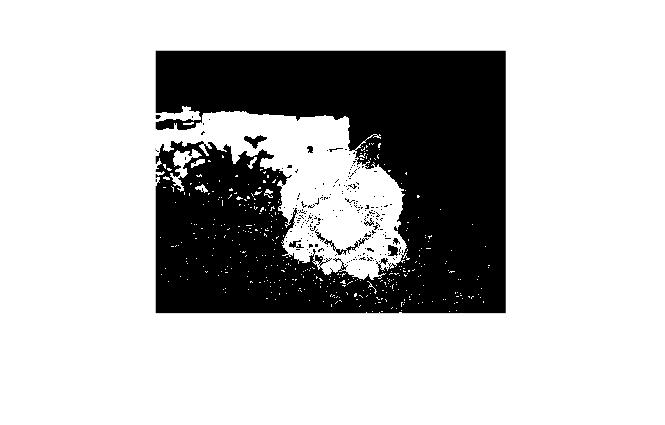

imshow(MFinG);

En aquest altre cas, la petita no detecta al gat, la mitjana l'enquadra bé, i la gran abasta massa informació.

Com veiem, els resultats obtinguts per aquest mètode són altament depenents de l'imatge.

## Funcions

function [rgb,MFin] = my_kmeans(I,O,k,rect)
    C = kmeans(O,k);
    IC = reshape(C,[size(I,1)],[size(I,2)]);
    rgb = label2rgb(IC);

    MASK = zeros(size(I,1),size(I,2));
    MASK(rect(2):(rect(2)+rect(4)),rect(1):(rect(1)+rect(3))) = 1;
    
    H = [C, MASK(:)];
    
    Hist0 = hist(H(H(:,2)==0),[1:k]); % H(:,2) == 0 retorna els valors fora del rectangle, 
                                      % H(H(:,2)==0) retorna els valors C de fora del rectangle
    Hist1 = hist(H(H(:,2)==1),[1:k]); % El mateix pels punts de dins
    
    RES = Hist1 > Hist0;
    
    M = RES(H(:,1)); %Elements d'H que cauen tenen una k a 1 a RES
    MFin = reshape(M,size(I,1),size(I,2));
end

function [rgb,MFin] = my_kmeans_c(I,O,k,mask)
    C = kmeans(O,k);
    IC = reshape(C,[size(I,1)],[size(I,2)]);
    rgb = label2rgb(IC);

    
    H = [C, mask(:)];
    
    Hist0 = hist(H(H(:,2)==0),[1:k]); % H(:,2) == 0 retorna els valors fora del rectangle, 
                                      % H(H(:,2)==0) retorna els valors C de fora del rectangle
    Hist1 = hist(H(H(:,2)==1),[1:k]); % El mateix pels punts de dins
    
    RES = Hist1 > Hist0;
    
    M = RES(H(:,1)); %Elements d'H que cauen tenen una k a 1 a RES
    MFin = reshape(M,size(I,1),size(I,2));
end